Tau = tand(25.52)/22;
alpha = 7.33/40;
P = 20.26;

num = 36.10*P;
den = [1 24.93 0];
L1 = tf(num,den)


L1 =
 
      731.4
  -------------
  s^2 + 24.93 s
 
Continuous-time transfer function.
Model Properties


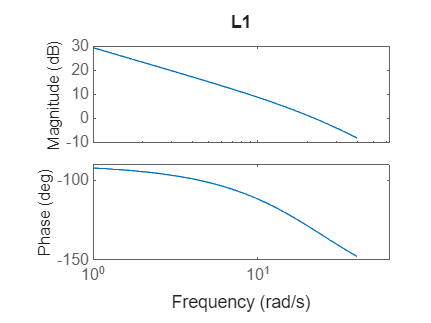

bodeplot(L1,{1,40})
title("L1")



C1 = tf([Tau 1],[alpha*Tau 1])


C1 =
 
   0.0217 s + 1
  --------------
  0.003977 s + 1
 
Continuous-time transfer function.
Model Properties


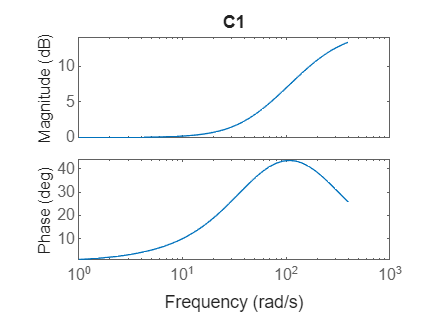

bodeplot(C1,{1,400})
title("C1")

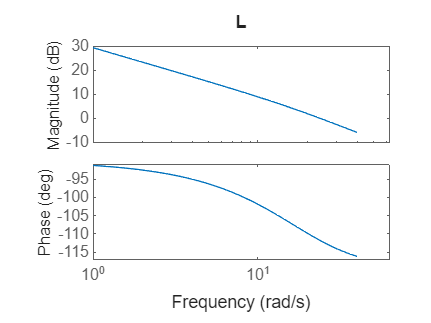



L = L1*C1;
bodeplot(L,{1,40})
title("L")






T = feedback(L1*C1,1,-1)


T =
 
               15.87 s + 731.4
  -----------------------------------------
  0.003977 s^3 + 1.099 s^2 + 40.8 s + 731.4
 
Continuous-time transfer function.
Model Properties


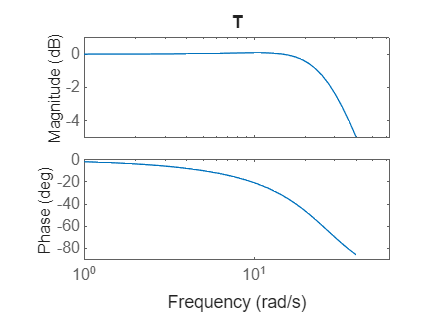

bodeplot(T,{1,40})
title("T")

## Verifcation

C = -P*C1;
plant = tf(-1.4479,[0.0401 1 0])


plant =
 
      -1.448
  --------------
  0.0401 s^2 + s
 
Continuous-time transfer function.
Model Properties



Loop = C*plant;
T_loop = feedback(Loop,1,-1)


T_loop =
 
                0.6366 s + 29.33
  ---------------------------------------------
  0.0001595 s^3 + 0.04408 s^2 + 1.637 s + 29.33
 
Continuous-time transfer function.
Model Properties


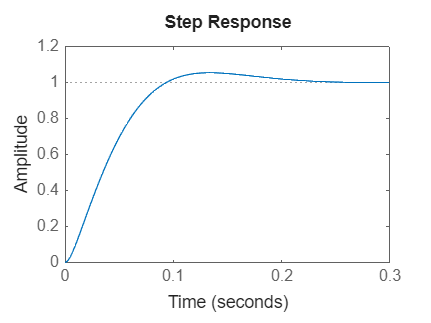


step(T_loop)